This script is a part of the supplementary material for the following paper:

-  Jamshidi Idaji et al,  "Nonlinear Interaction Decomposition (NID): A Method for Separation of Cross-frequency Coupled Sources in Human Brain". doi: [https://doi.org/10.1016/j.neuroimage.2020.116599](https://doi.org/10.1016/j.neuroimage.2020.116599)

(C) Please cite the above paper  in case of any significant usage of this script.

Corresponding Author: Vadim V. Nikulin (nikulin@cbs.mpg.de)

(C) Mina Jamshidi Idaji, Oct 2019, @ MPI CBS, Leipzig, Germany

jamshidi@cbs.mpg.de    .         minajamshidi91@gmail.com

https://github.com/minajamshidi/NID

# **Supplementary Code (3)**

# Separating a Source with Non-sinusoidal Waveform with NID

In this script, we provide a realistic simulation of EEG signals, where a single dipole source with a non-sinusoidal waveform is mixed with 1/f noise produced by multiple dipoles. For this script, you will need the [METH toolbox](https://www.uke.de/english/departments-institutes/institutes/neurophysiology-and-pathophysiology/research/research-groups/index.html). Additionally, you need our codes for this manuscript, which you can download from our [GitHub](https://github.com/minajamshidi/NID).

Add the path of METH and our codes to your MATLAB.

%NID_dir = './NID_GitHub'; % you may add your own directory
% meth_dir = './meth' % you may add your own directory
%addpath(genpath(meth_dir));
%addpath(genpath(NID_dir));

First, we set the simulation parmeters:

fs = 256; % sampling rate
T_sec = 10*60; % length of the simulated signal in seconds
n_samples = T_sec*fs; % number of time samples
times = (0:n_samples-1)/fs; % the time samples

Then, we build a source signal with non-sinusoidal waveform (a rectified cosine):

s = abs(cos(2*pi*10*times)) - .5;

time_idx = 2*fs:4*fs;
figure,

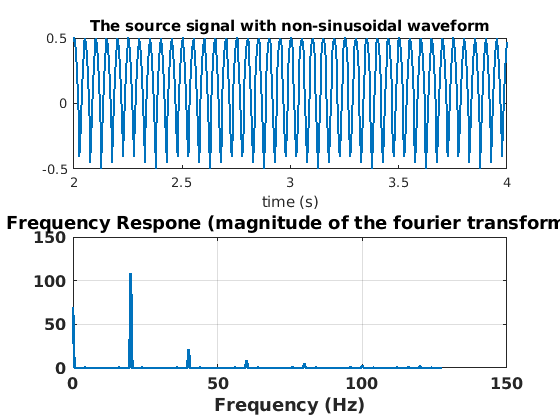

subplot(2,1,1)
plot(times(time_idx), s(time_idx), 'linewidth', 2), xlabel('time (s)')
title('The source signal with non-sinusoidal waveform')
subplot(2,1,2),
plot_freqResp(s, fs, 2*fs)
title('Frequency Respone (magnitude of the fourier transform)')
set(gca,'fontweight','bold','fontsize',12)

we give the built signal to our EEG-simulation function, which will mix locate it in a random position with a random oriented dipole, and then mix it with 100 pink noise sources at random positions with random orientations.

seed = 3656278 % for reproduction purpose: these were randomely generated numbers

seed = 3656278

%seed = randperm(9999999, 1); % you may generate new seeds
SNR = 1;
rng(seed, 'twister')
[ eeg, pattern_sig, electrode_locs ] = Produce_EEG(1, fs, SNR, s');

Now that we have a simulated EEG multi-channel signal, we can apply NID on it:

FrP = 1;
FrQ = 2;
F_base = 20;
[Success,A_final_p,A_final_q,out_ICA,ICA_Method,D_synch,SynchFac_mean,out_ssd,IDX_src,Xp,Xq] = ...
                NID(eeg, FrP, FrQ, F_base, 'source_set_num', 1, 'ssd_or_bp', [1 1], 'fs', fs, 'synchtype', 1);

SSD: Input data does not have full rank. Only 48 components can be computed.
SSD: Input data does not have full rank. Only 56 components can be computed.
Do ICA~~~~~~~~~~~~~~~~~~~~~~
~~~~~~~~~~~~~~~~~~~~~~
Number of signals: 2
Number of samples: 153600
Calculating covariance...
Dimension not reduced.
Selected [ 2 ] dimensions.
Smallest remaining (non-zero) eigenvalue [ 0.205395 ]
Largest remaining (non-zero) eigenvalue [ 35.6459 ]
Sum of removed eigenvalues [ 0 ]
[ 100 ] % of (non-zero) eigenvalues retained.
Whitening...
Check: covariance differs from identity by [ 1.33227e-15 ].
Used approach [ defl ].
Used nonlinearity [ e5 ].
Starting ICA calculation...
IC 1 .......computed ( 7 steps ) 
IC 2 ..computed ( 2 steps ) 
Done.
Adding the mean back to the data.
jade -> Looking for 2 sources
jade -> Removing the mean value
jade -> Whitening the data
jade -> Estimating cumulant matrices
jade -> Contrast optimization by joint diagonalization
jade -> Sweep #  0 completed in 1 rotations
jade ->

We expect that NID finds a pair of coupled narrow-band (20 Hz and 40 Hz) source signals with similar mixing patterns. Let's look at the extracted mixing patterns and the original simulated one:

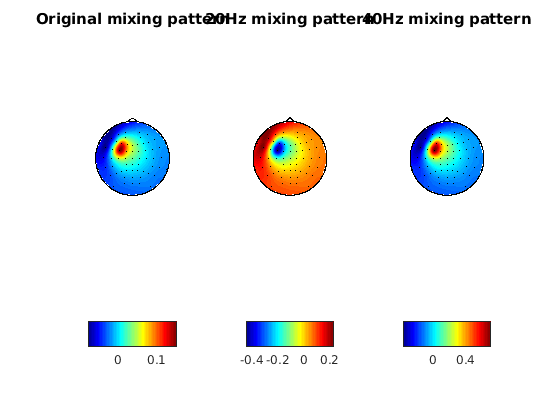

figure,  
subplot(1, 3,1),
showfield(pattern_sig, electrode_locs); title('Original mixing pattern'),
colorbar('off'), colorbar('southoutside')
set(findall(gca, 'type', 'text'), 'visible', 'on')  
subplot(1,3,2),
showfield(A_final_p, electrode_locs); title('20Hz mixing pattern'),
colorbar('off'), colorbar('southoutside')
set(findall(gca, 'type', 'text'), 'visible', 'on')  
subplot(1,3,3), 
showfield(A_final_q, electrode_locs);  title('40Hz mixing pattern'),
colorbar('off'), colorbar('southoutside')
set(findall(gca, 'type', 'text'), 'visible', 'on')   

Let's check the simuilarity of patterns nummerically:

sim_p_sig = dot(A_final_p, pattern_sig)/norm(A_final_p)/norm(pattern_sig)

sim_p_sig = -1.0000

sim_q_sig = dot(A_final_q, pattern_sig)/norm(A_final_q)/norm(pattern_sig)

sim_q_sig = 1.0000

sim_p_q = dot(A_final_p, A_final_q)/norm(A_final_p)/norm(A_final_q)

sim_p_q = -1.0000

We see that the spatial patterns are almost similar. In such a case, it can be that the coupling is because of non-sinusoidal waveform of an oscillation with the detected spatial pattern.  Therefore, we filter the broadband signal with the spatial filter of the separated sources above. First, let's look at the spatial filters of the NID components:

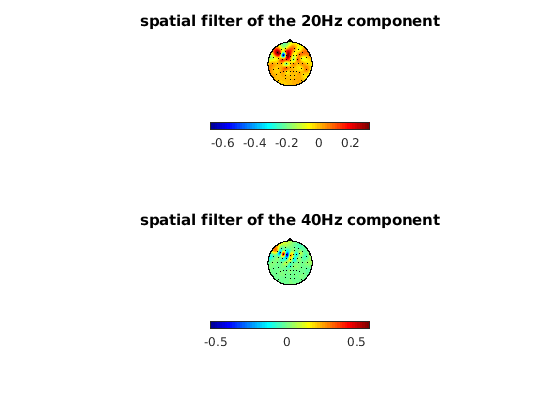

W_ICA_p = out_ICA.W_ICA(:,1);
W_ssd_p = out_ssd.W_ssd{1};
Wp = W_ICA_p*W_ssd_p';
Wp = Wp(IDX_src,:); % 20Hz spatial filter
Wp = Wp/norm(Wp);

W_ICA_q = out_ICA.W_ICA(:,2);
W_ssd_q = out_ssd.W_ssd{2};
Wq = W_ICA_q*W_ssd_q';
Wq = Wq(IDX_src,:); %40Hz spatial filter
Wq = Wq/norm(Wq);

figure,  
subplot(2, 1,1),
showfield(Wp, electrode_locs); title('spatial filter of the 20Hz component'),
colorbar('off'), colorbar('southoutside')
set(findall(gca, 'type', 'text'), 'visible', 'on')  
subplot(2,1,2),
showfield(Wq, electrode_locs); title('spatial filter of the 40Hz component'),
colorbar('off'), colorbar('southoutside')
set(findall(gca, 'type', 'text'), 'visible', 'on')  

Now that we looked at the spatial filters, we filter the broadband signal with these spatial filters:

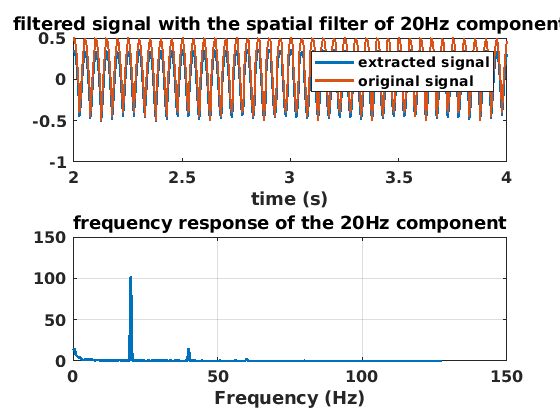

src_p = Wp*eeg';
src_q = Wq*eeg';

figure,
subplot(2,1,1),
plot(times(time_idx), sign(sim_p_sig)*src_p(time_idx), 'linewidth', 2), xlabel('time (s)')
hold on,
plot(times(time_idx), s(time_idx), 'linewidth', 2),
title('filtered signal with the spatial filter of 20Hz component')
legend('extracted signal', 'original signal')
set(gca,'fontweight','bold','fontsize',12)
subplot(2,1,2),
plot_freqResp(src_p, fs, 2*fs)
title('frequency response of the 20Hz component')
set(gca,'fontweight','bold','fontsize',12)

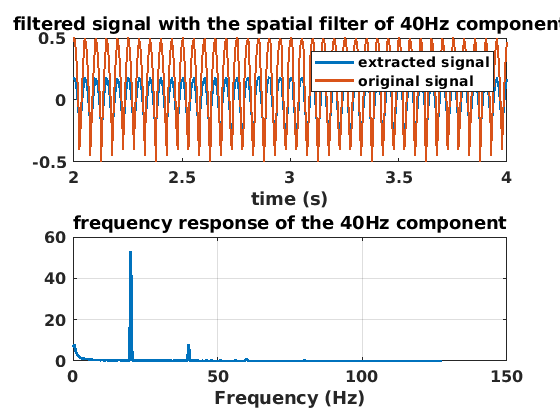



figure, 
subplot(2,1,1),
plot(times(time_idx), sign(sim_q_sig)*src_q(time_idx), 'linewidth', 2), xlabel('time (s)')
hold on,
plot(times(time_idx), s(time_idx), 'linewidth', 2),
legend('extracted signal', 'original signal')
title('filtered signal with the spatial filter of 40Hz component')
set(gca,'fontweight','bold','fontsize',12)

subplot(2,1,2),
plot_freqResp(src_q, fs, 2*fs)
title('frequency response of the 40Hz component')
set(gca,'fontweight','bold','fontsize',12)

We see that the non-sinusoidal waveform is well-extracted. 

Note that for visualization purpose, we multiplied the extracted sources by the sign of the similarity of the patterns and the simulated source pattern. We know that most of source-separation methods (e.g. ICA) may cause an inversion of sign in the separated source.

## Conclusion

It is important to keep in mind that: 

- **from a signal-processing perspective, a non-sinusoidal waveform is a linear mixture of narrow-band signals.** **Therefore, in the context of CFC,**** a powerful source-separation method is expected to separate CFC oscillations at the location of the non-sinusoidal signal.** As shown in this script, if the spatial pattern of the separated coupled oscillations are similar, we can filter the broadband signal to find a single source with non-sinusoidal waveform. 

- **NID, and any other source-separation method, separates coupled narrow-band oscillations and it is a matter of post-processing to distinguish the genuine CFC interaction and sources with non-sinusoidal waveshape**. In this script, we illustrated the latter.

- If 10-Hz and 20-Hz oscillations originate from the same spatial location, there can be two scenarios: (1) there are two distinct CFC processes observed at that location (2) there is one complex process with two components which are coupled to each other. Actually, in principle, it is not possible to distinguish these two scenarios with signal processing tools, as we do not have enough spatial resolution. It is up to the researcher to make neuro-physiological interpretations about the coupled processes.  

## **Functions**

function plot_freqResp(x, fs, nfft)
    X1_fft = fft(x, nfft);
    f = (0:fix(nfft/2)-1)*2/nfft;
    X = X1_fft(1:fix(nfft/2));
    f = f*fs/2;
   
    plot(f,abs(X), 'linewidth', 2);
    xlabel('Frequency (Hz)','fontsize',12);
    grid on,
end

**Notification: **

THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS" AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT LIMITED TO, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE ARE DISCLAIMED. IN NO EVENT SHALL THE COPYRIGHT HOLDER OR CONTRIBUTORS BE LIABLE FOR ANY DIRECT, INDIRECT, INCIDENTAL, SPECIAL, EXEMPLARY, OR CONSEQUENTIAL DAMAGES (INCLUDING, BUT NOT LIMITED TO, PROCUREMENT OF SUBSTITUTE GOODS OR SERVICES; LOSS OF USE, DATA, OR PROFITS; OR BUSINESS INTERRUPTION) HOWEVER CAUSED AND ON ANY THEORY OF LIABILITY, WHETHER IN CONTRACT, STRICT LIABILITY, OR TORT (INCLUDING NEGLIGENCE OR OTHERWISE) ARISING IN ANY WAY OUT OF THE USE OF THIS SOFTWARE, EVEN IF ADVISED OF THE POSSIBILITY OF SUCH DAMAGE.